# Perform Positional Accuracy Analysis for a 3D Printing Cartesian Robot

This example shows how to perform positional accuracy analysis for a 3D Printing Cartesian robot.

To return to the main page within this repository, [click here](matlab:web('CartesianRobotDesignOverview.html')).

## Precision and Accuracy of a Cartesian Robot

This section describes precision and accuracy of a Cartesian Robot. Precision in Cartesian robots refers to the ability of the robot to consistently repeat a specific position or path, indicating minimal deviation from a desired target point across multiple attempts. Accuracy describes how close the actual position of the robot is to the intended target position. Both precision and accuracy are crucial for Cartesian robots as they directly affect the quality and reliability of operations such as assembly, machining, or 3D printing. High precision ensures that the robot can perform repetitive tasks with minimal variation, which is essential for maintaining consistency in production processes. High accuracy ensures that each task is executed correctly according to design specifications, which is vital in industries requiring tight tolerances, such as electronics manufacturing and aerospace component assembly. Together, precision and accuracy reduce the need for rework, minimize material waste, and enhance overall productivity. Additionally, they contribute to safer operations by preventing errors that could lead to collisions or damage, ensuring a reliable and efficient operational environment.

The following image shows the major factors impacting precision and accuracy for a Cartesian robot. This example focuses on measuring and plotting positional accuracy for a XYZ Cartesian robot with Gantry configuration used for 3D printing applications.

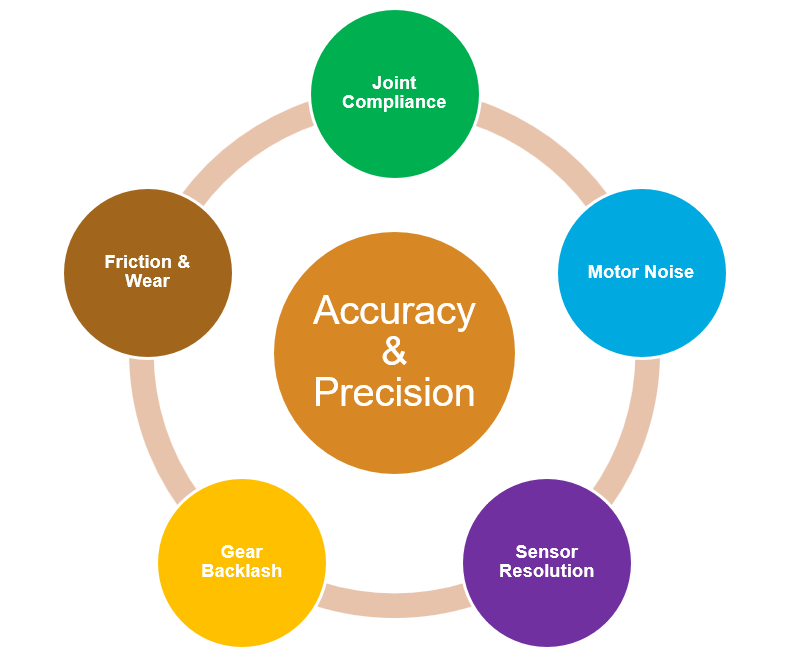

## Positional Accuracy of a Cartesian Robot

Positional accuracy for a Cartesian robot refers to the degree to which the actual position of the robot matches the intended target position. It is a measure of the ability of the robot to reach a specific point as defined by its control system, reflecting the closeness of the achieved position to the desired coordinates.

Positional accuracy is quantified in terms of error of the actual or measured position with respect to the intended target position. This example demonstrates the use of root mean squared (RMS) error to signify positional accuracy. Position can be measured by various types of position sensor. Typically, Linear Encoders, Optical Encoders, or Linear Variable Differential Transformers (LVDTs) are used as position sensors for high precision application like 3D printing and precision manufacturing. Potentiometers are used for applications where precision is not extremely critical like material handling. Laser distance sensors are used for very high-precision applications.


$$x_{\textrm{error}} =x_{\textrm{measured}} -x_{\textrm{target}}$$


where,

$x_{\textrm{error}}$ is the error in position. Lower the value, higher is the accuracy.

$x_{\textrm{measured}}$ is the actual or measured position, provided by position sensor.

$x_{\textrm{target}}$ is the intended target position.

## Build Cartesian Robot Model Components 

### Model Robot Mechanism

Run the parameter script. Load the robot model.

parameterScript = 'XYZGantryRobotParameters';
run(parameterScript);
modelName = 'XYZCartesianRobot3DPrinting';
load_system(modelName)

In this example, the robot model is configured for a XYZ Gantry robot. 

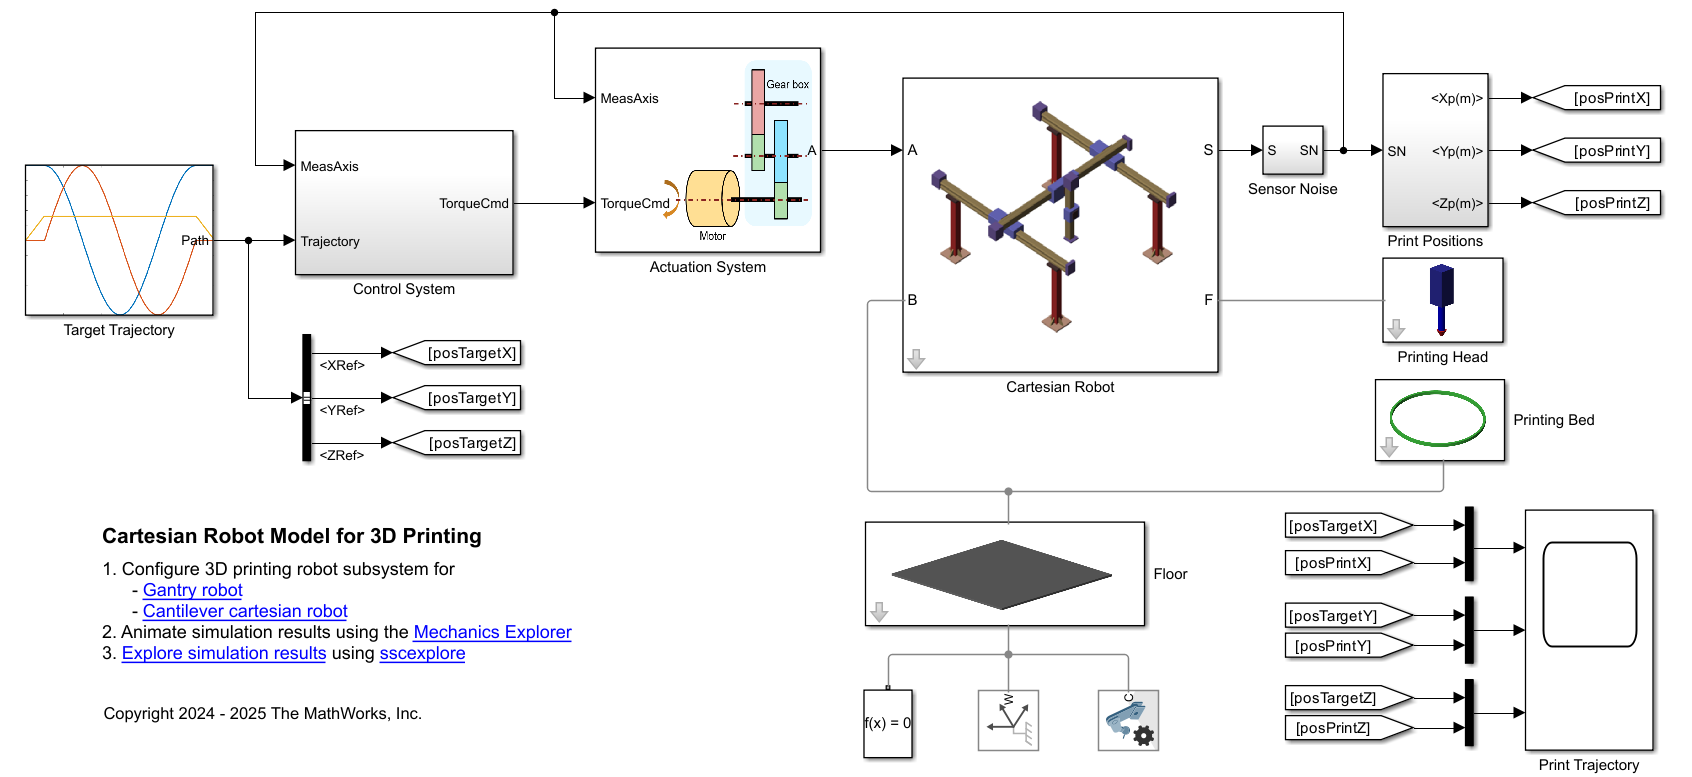

The robot consists of four linear stages, two for X-axis, and each for Y-axis and Z-axis. A linear stage is the mechanism that converts rotary motion of motor to linear motion. Each linear stage consists of a fixed linear guide and a moving carriage that are connected using the Prismatic Joint block. Model the linear stage using a custom library block Linear Stage. Provide actuation force input to each of the prismatic joints. Sense position, velocity, acceleration from each of the joints. You can feed the sensed position and velocity signals to the actuation system and feedback control system to generate the motor torque commands for X, Y and Z axes. Specify spring stiffness and damping coefficient of the prismatic joints. Set lower limit and upper limit for these joints. 

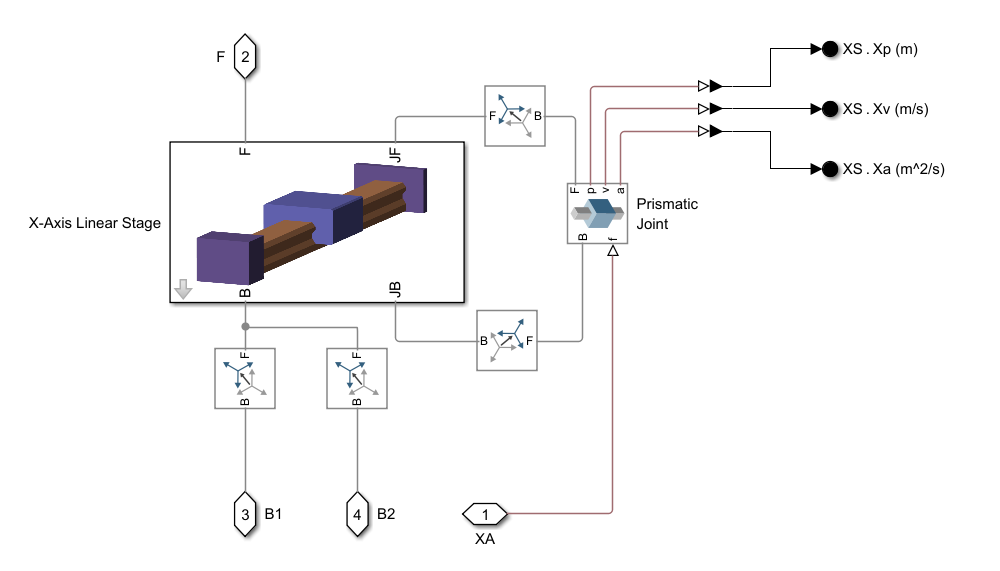

### Model Actuation System

The Actuation System subsystem models the motor, driver, and gear for each axis. The Motor & Drive block represents a generic motor and drive operating in torque-control mode, or equivalently current-control mode. You can use it to represent a servomotor at a system level. Typically, for large Cartesian robots requiring high precision, a servomotor is the ideal choice. Permissible range of torques and speeds of the motor is defined by a torque-speed envelope, and the output torque tracks the torque reference demand Tr with time constant Tc. The block is connected to a DC Voltage Source. The block produces a positive torque acting from the mechanical C to R ports.

You can provide motor inertia and damping using Inertia and Rotational Damper blocks, respectively.

The Simple Gear block represents a fixed-ratio gear or gear box. No inertia or compliance is modeled in this block. In this example, it is assumed that no losses due to gear meshing, backlash and bearing lubrication viscosity are present. It is important to note that positional accuracy of a linear stage is affected by presence of gear friction, backlash and viscous losses.

The Wheel and Axle block represents an ideal converter between mechanical rotational and mechanical translational motions. Use this block to model actuation mechanisms like rack-pinion, ball screw, and leadscrew. In this example, the linear stage drive mechanism is an abstract model. Mechanisms like belt drive, rack-pinion, leadscrew are not modeled in detail. It is important to note that positional accuracy of a linear stage is affected by the drive mechanism.

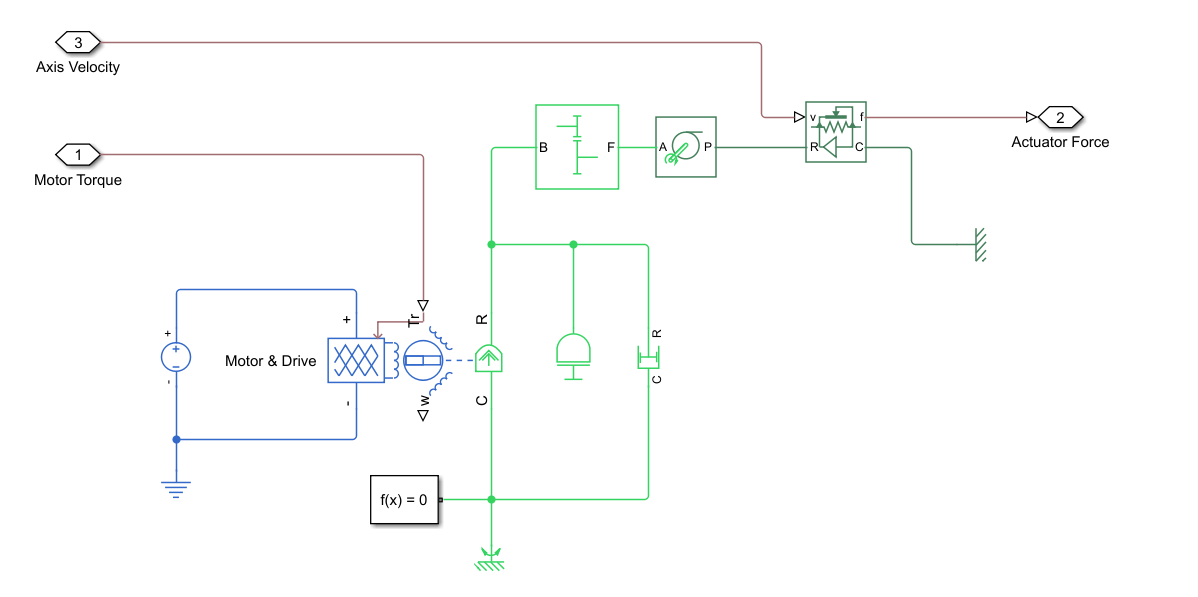

### Model Control System

The Control System subsystem models the control system for each axis of the Cartesian robot. Use a cascade control system to model an effective control system with enhanced system performance. The inner loop controls velocity and attenuates high-frequency noise. The control variable for the outer loop is position, which reduces the effects of low-frequency disturbances. 

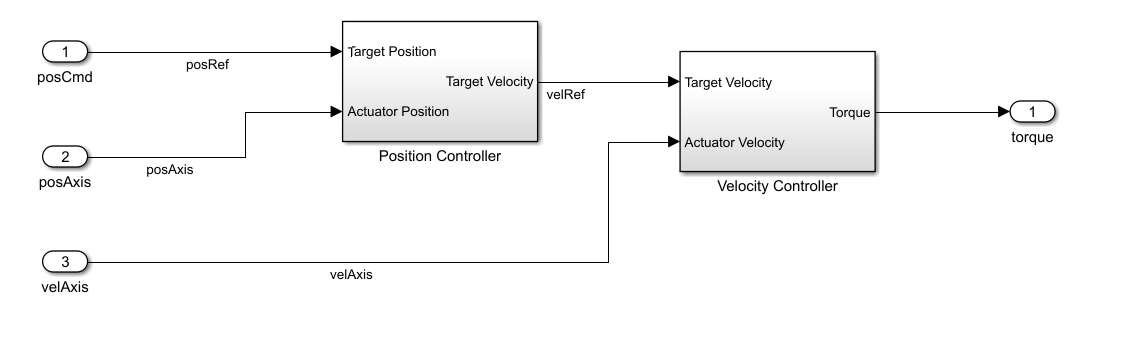

The position controller (outer loop) is a PID controller that receives the intended target position as a command and the measured linear stage axis position as feedback to compute the target velocity for the velocity controller (inner loop).

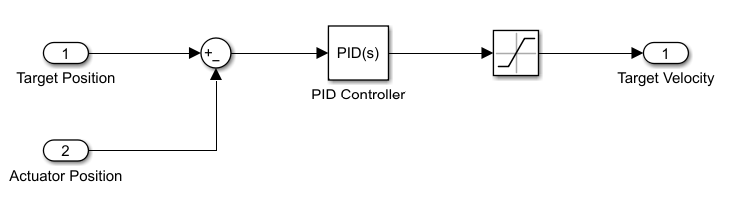

The velocity controller is a PID controller that receives the target velocity from the position controller as a command and the measured linear stage axis velocity as feedback to compute the motor torque command.

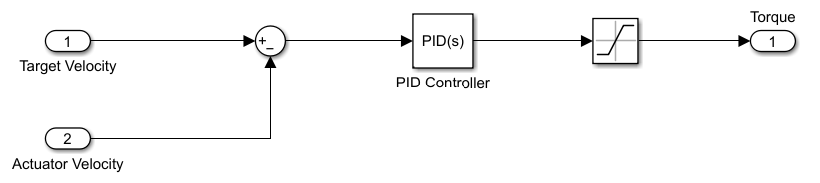

Tune the PID controllers to minimize positional and velocity error by attenuating both high- and low-frequency disturbances. To achieve high positional accuracy, carefully tune both PID controllers.

## Simulate Model and Compute Positional Accuracy

To run the model with temporary changes to model parameters and block parameters, define a Simulink.SimulationInput object.

simIn = Simulink.SimulationInput(modelName);

Set the stop time for the simulation.

SimT = 30;
simIn = setModelParameter(simIn,"StopTime",string(SimT));

### Compute Positional Accuracy without Sensor Noise

Positional accuracy of Cartesian robots is sensitive to sensor noise. Position sensor noise is a high frequency additive component in the measured position signal. In this example, the Band-Limited White Noise block models a random noise generator. You can vary the sensor noise intensity by specifying the value of Gain block connected to the Band-Limited White Noise block. Set the noise intensity to zero.

simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Pose Noise/Noise Intensity","Gain","0");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Pose Noise/Noise Intensity","Gain","0");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Vel Noise/Noise Intensity","Gain","0");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Vel Noise/Noise Intensity","Gain","0");

Run the model.

simOut = sim(simIn);

Plot the radial positional error for printed circle trajectory by using the function `estimatePositionalError`.

Plotting positional error in mm for 3D-printed circle


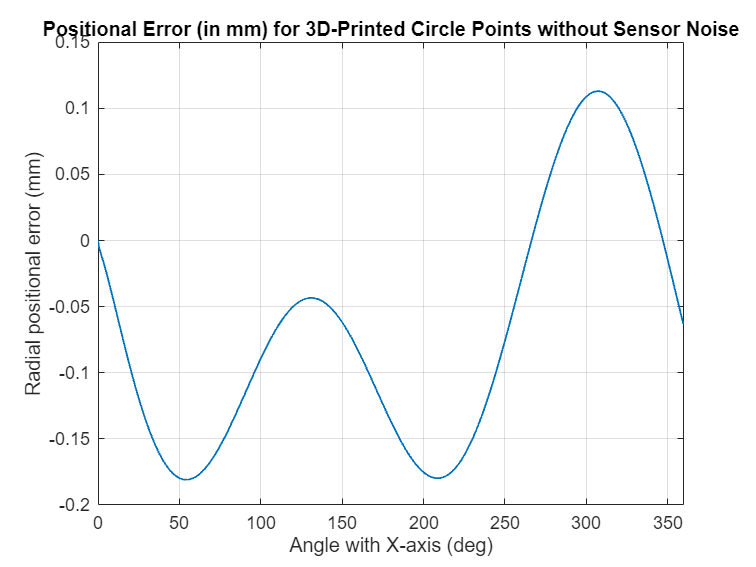

errorPoseWOutNoise = estimatePositionalError(logsout=simOut.logsoutCartesianRobot3DPrinting,trajectory=Trajectory,...
    errorPlotTitle='Positional Error (in mm) for 3D-Printed Circle Points without Sensor Noise');

Compute the RMS value of the positional error. This is a measure of the positional accuracy of the 3D printing XYZ Cartesian robot with Gantry configuration without sensor noise.

fprintf('Positional error (RMS) for 3D-printed circle radius without sensor noise is %6.3f mm\n', errorPoseWOutNoise.RMS)

Positional error (RMS) for 3D-printed circle radius without sensor noise is  0.113 mm


fprintf('Maximum positional error for 3D-printed circle radius without sensor noise is %6.3f mm\n', errorPoseWOutNoise.max)

Maximum positional error for 3D-printed circle radius without sensor noise is  0.181 mm


The desired level of accuracy depends on the application. For a typical 3D printing application for industrial manufacturing, the desired accuracy varies from 0.01 - 1 mm. Both the RMS positional error and maximum positional error meet the accuracy requirement.

### Compute Positional Accuracy with Sensor Noise

In 3D printing Cartesian robots, noise can significantly impact the accuracy and precision of the printed objects. 

- Mechanical noise, caused by vibrations from motors and linear stages, can lead to layer misalignment and surface imperfections. 

- Electrical noise originates from electromagnetic interference and can disrupt the signals to the motors and sensors, causing positional errors. 

- Sensor noise results from inaccuracies or fluctuations in sensor readings, further degrading the accuracy of the printing process. 

- Environmental noise, such as temperature fluctuations and air current, influences the material deposition process, leading to warping or inconsistent layer adhesion. 

- Quantization noise results from translating a continuous design into discrete layers, limited by the printer's resolution.

This example demonstrates the impact of sensor noise on positional accuracy.

For a typical Optical Encoder position sensor, the maximum sensor noise is about 0.05 - 0.1 % of the full-scale range of measurement. In this example, the stroke of X-axis is 3000 mm. So, the full-scale range of position sensor is considered a little above 3000 mm. Use Band-Limited White Noise block and Gain block to represent a randomly generated sensor noise.

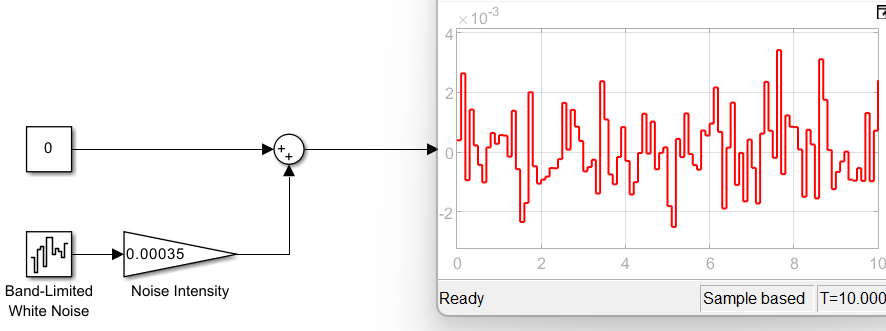

To have unique noise distribution for different sensors, specify different starting seed values for the random number generator. To achieve a sensor noise intensity about 0.15 % of the full-scale range, set the noise intensity to 0.00035.

simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Pose Noise/X Position Sensor White Noise","seed","[4321]");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Pose Noise/Noise Intensity","Gain","0.00035");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Pose Noise/Y Position Sensor White Noise","seed","[23341]");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Pose Noise/Noise Intensity","Gain","0.00035");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Vel Noise/X Velocity Sensor White Noise","seed","[32411]");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/X Vel Noise/Noise Intensity","Gain","0.00035");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Vel Noise/Y Velocity Sensor White Noise","seed","[1324]");
simIn=setBlockParameter(simIn,modelName+"/Sensor Noise/Y Vel Noise/Noise Intensity","Gain","0");

Run the model.

simOut = sim(simIn);

Plot the radial positional error for printed circle trajectory by using the function `estimatePositionalError`.

Plotting positional error in mm for 3D-printed circle


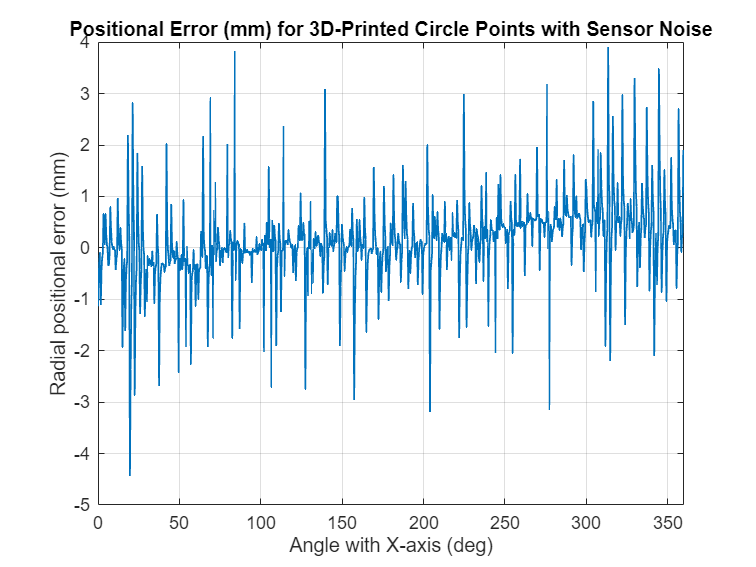

errorPoseWNoise = estimatePositionalError(logsout=simOut.logsoutCartesianRobot3DPrinting,trajectory=Trajectory,...
    errorPlotTitle='Positional Error (mm) for 3D-Printed Circle Points with Sensor Noise');

Compute the RMS value of the positional error. This is a measure of the positional accuracy of the 3D printing XYZ Cartesian robot with Gantry configuration exposed to sensor noise.

fprintf('Positional error (RMS) for 3D-printed circle radius with sensor noise is %6.3f mm\n', errorPoseWNoise.RMS)

Positional error (RMS) for 3D-printed circle radius with sensor noise is  0.808 mm


fprintf('Maximum positional error for 3D-printed circle radius with sensor noise is %6.3f mm\n', errorPoseWNoise.max)

Maximum positional error for 3D-printed circle radius with sensor noise is  4.419 mm


### Impact of Sensor Noise on Positional Accuracy

Plot the radial positional error for printed circle trajectory with and without sensor noise.

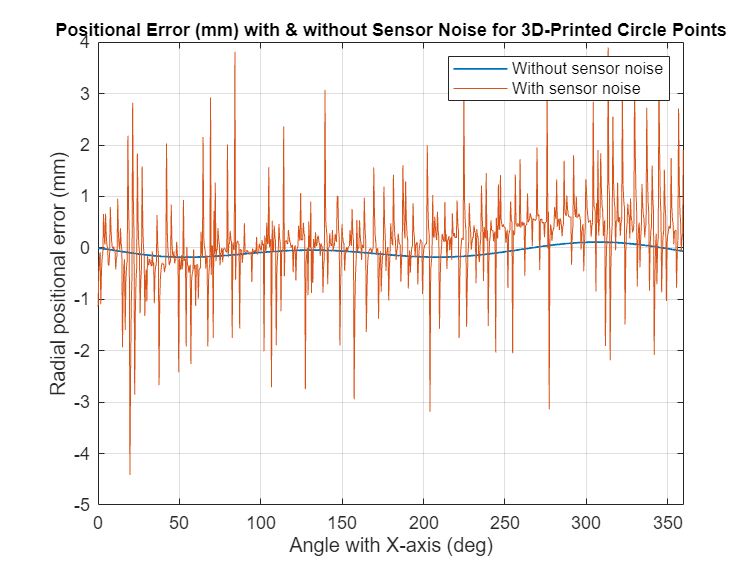

figure;
plot(errorPoseWOutNoise.angle,errorPoseWOutNoise.rError,LineWidth=1)
hold on
title('Positional Error (mm) with & without Sensor Noise for 3D-Printed Circle Points')
ax = gca;
ax.TitleFontSizeMultiplier = 1;
xlabel('Angle with X-axis (deg)') 
ylabel('Radial positional error (mm)') 
plot(errorPoseWNoise.angle,errorPoseWNoise.rError,LineWidth=0.5)
legend({'Without sensor noise','With sensor noise'},'Location','northeast')
grid on
xlim([0 360])

Compare the radial positional errors for sensor measurements with and without noise in a table. The table shows values of RMS and maximum radial positional error in mm.

Measurement = ["WithoutNoise";"WithNoise"];
RMSError = [errorPoseWOutNoise.RMS;errorPoseWNoise.RMS];
MaxError = [errorPoseWOutNoise.max;errorPoseWNoise.max];
errorTable = table(Measurement,RMSError,MaxError)

errorTable = 2×3 table
     Measurement      RMSError    MaxError
    ______________    ________    ________

    "WithoutNoise"    0.11309     0.18092 
    "WithNoise"       0.80821      4.4186 


The presence of sensor noise negatively impacts the mean and maximum positional errors of 3D printing. An increased noise intensity will increase the positional errors. The desired level of accuracy depends on the application. For a typical 3D printing application for industrial manufacturing, the desired accuracy varies from 0.01 - 1 mm. The RMS error obtained with sensor noise indicates a 3D printing with fairly good accuracy, but the maximum error violates the requirement.

## Conclusion

From the above plots, mean and maximum values of positional error, you can infer that sensor noise affects positional accuracy. It is desirable to use high-precision sensors for applications with high demand of precision such as 3D printing. You can use signal filtering techniques like low-pass filters or Kalman filters to attenuate the high frequency noise. Tune the controllers with robust feedback control systems or adaptive algorithms to achieve a higher accuracy.

Copyright 2024 - 2025 The MathWorks, Inc.